# Create and Customize 3-D Horizontal Bar Graphs

3-D horizontal bar graphs present data with 3-D rectangular bars with lengths proportional to the values that they represent.

### Read Temperature Data

We will use `'BostonTemp.mat' `to demonstrate how to create and customize 3-D horizontal bar graphs. The MAT-file contains monthly temperature data of Boston, MA (Logan Airport) by the U.S. National Oceanic and Atmospheric Administration between 2000 and 2020. 

load BostonTemp.mat

### Basic 3-D Bar Graph

Visualize the monthly temperature for five consecutive years between 2000 and 2020.

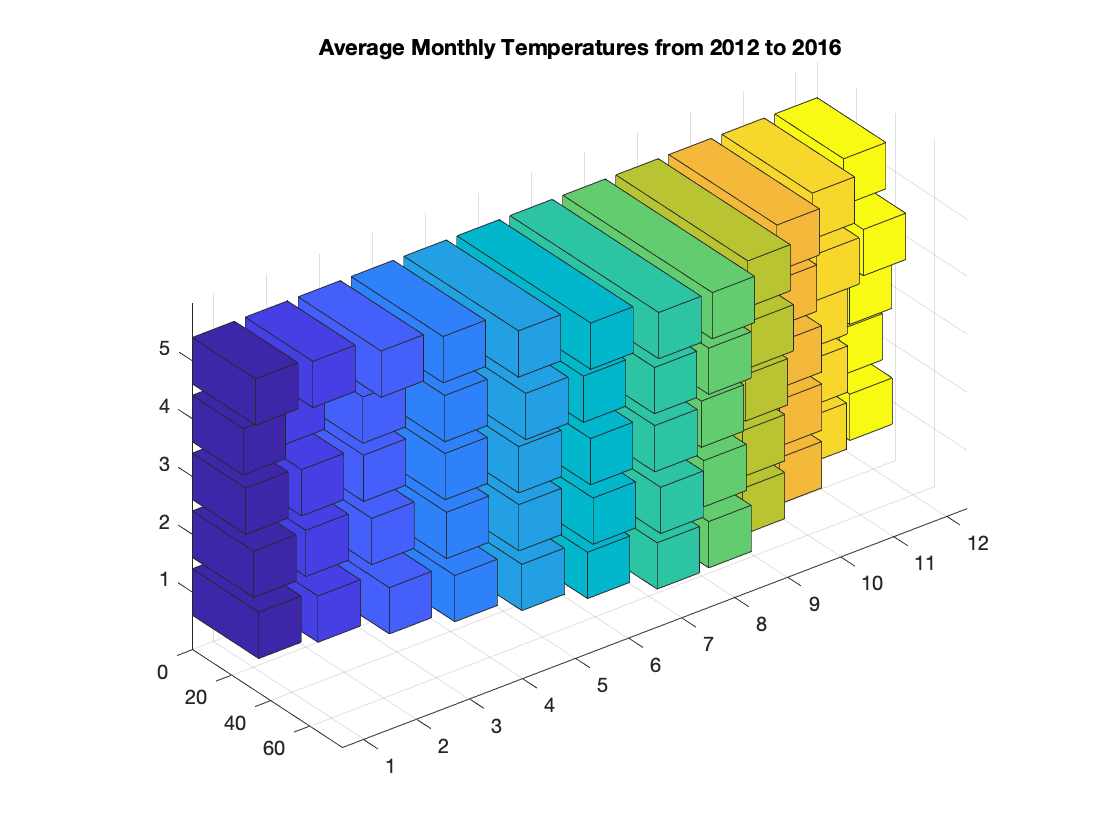

yearIdx = 13;      % Choose the first year of five to visualize monthly temperature
TempData5Years = Temperatures(yearIdx:yearIdx+4,:);

bar3h(TempData5Years);
title(sprintf("Average Monthly Temperatures from %d to %d",Year(yearIdx),Year(yearIdx+4)))

## Customization

### Customize Bar Width and Color

A bar graph can be customized to have user-specified bar width and color. Use the third argument to `bar3h` to modify the bar width. Modify the *CData*, and *FaceColor *properties using dot notation. When *CData* is set to *YData*, the bar color becomes a gradient based on the y-axis temperature values.

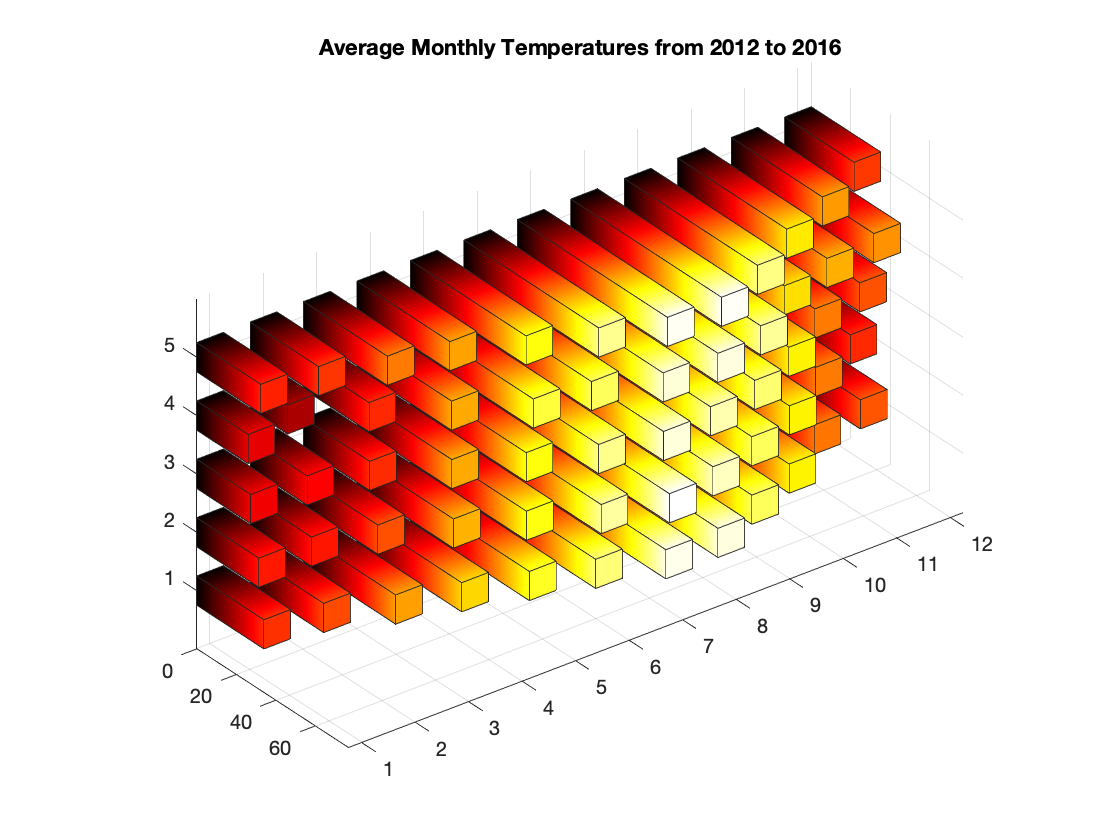

barWidth = 0.5;
figure
b = bar3h(TempData5Years,barWidth);   % Specify bar width in the third argument

colormap hot           % Choose a colormap
for k = 1:length(b)
    ydata = b(k).YData;               % Use YData property to create color gradient
    b(k).CData = ydata;               % Set CData property to Ydata
    b(k).FaceColor = "interp";        % Set the FaceColor to 'interp' to enable the gradient 
end
title(sprintf("Average Monthly Temperatures from %d to %d",Year(yearIdx),Year(yearIdx+4)))

### Customize Axes

Add axes labels, custom axes tick labels using the `x, y `and z`ticklabels `commands. Use `box`* on* to create a bounding box around the axes.

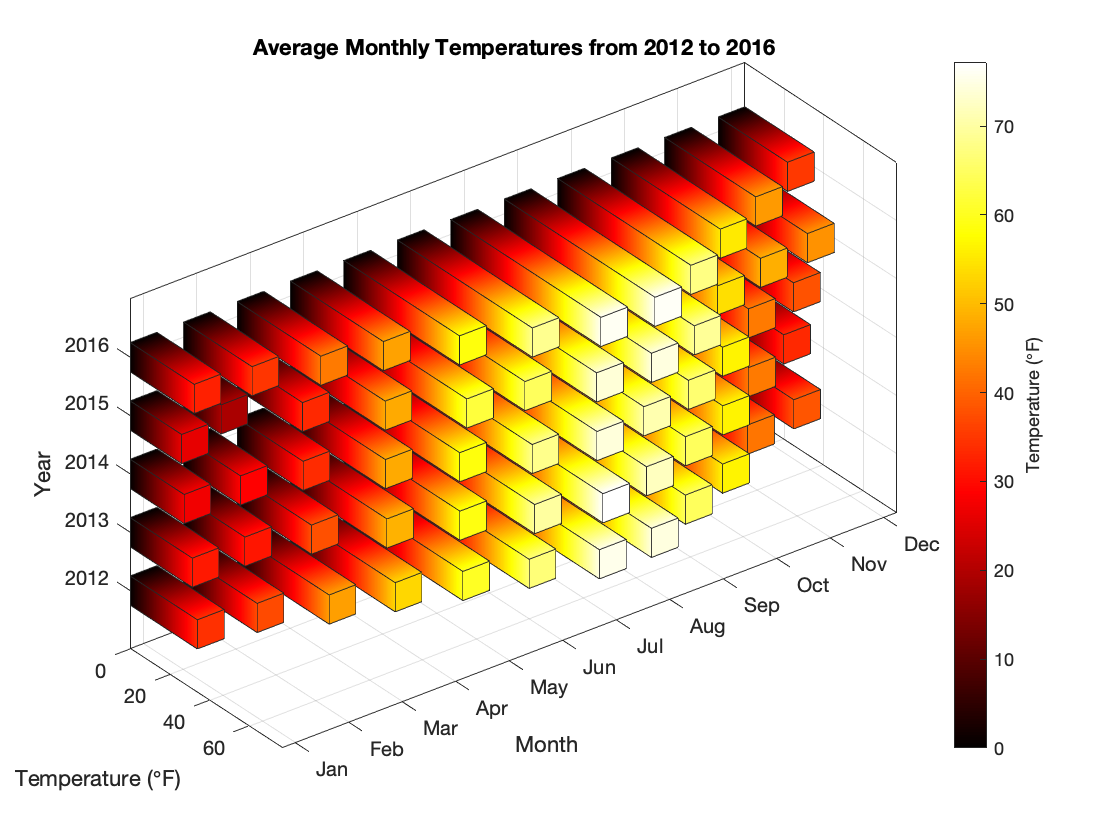

xlabel("Month")
zlabel("Year")
ylabel("Temperature (\circF)")

xticklabels(Months)
zticklabels(Year(yearIdx):Year(yearIdx+4))

ylabel(c, "Temperature (\circF)");
box on

## **Additional Information**

### **Get All Surface Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a Surface, uncomment the following code. View or modify these properties using dot notation.

% get(b(1))

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[3-D Horizontal Bar Chart](https://www.mathworks.com/help/matlab/ref/bar3h.html)

Copyright (c) 2021, The MathWorks, Inc.